# Map generation for coverage algorythms

## Setting parameters for map creation

randomMap = true;
randomSeed = 5;
if (~randomMap)
    rng(randomSeed,"twister");
end
mapWidth = 20;
mapLength = 20;
numberOfObstacles = 5;
obstacleMaxSize = 4;

% Create the binary occupancy map object
omap = binaryOccupancyMap(mapLength, mapWidth);

## Generate obstacles

obstacleNumber = 1;
while obstacleNumber <= numberOfObstacles
    width = randi([1 obstacleMaxSize],1);                 % The largest integer in the sample intervals for obtaining width, length and height                                                     
    length = randi([1 obstacleMaxSize],1);                % can be changed as necessary to create different occupancy maps.
    xPosition = randi([0 mapWidth-width],1);
    yPosition = randi([0 mapLength-length],1);
    
    [xObstacle,yObstacle] = meshgrid(xPosition:xPosition+width,yPosition:yPosition+length);
    xyObstacles = [xObstacle(:) yObstacle(:)];
    
    checkIntersection = false;
    for i = 1:size(xyObstacles,1)
        if checkOccupancy(omap,xyObstacles(i,:)) == 1
            checkIntersection = true;
            break
        end
    end
    if checkIntersection
        continue
    end
    
    setOccupancy(omap,xyObstacles,1)
    
    obstacleNumber = obstacleNumber + 1;
end

## Display generated map

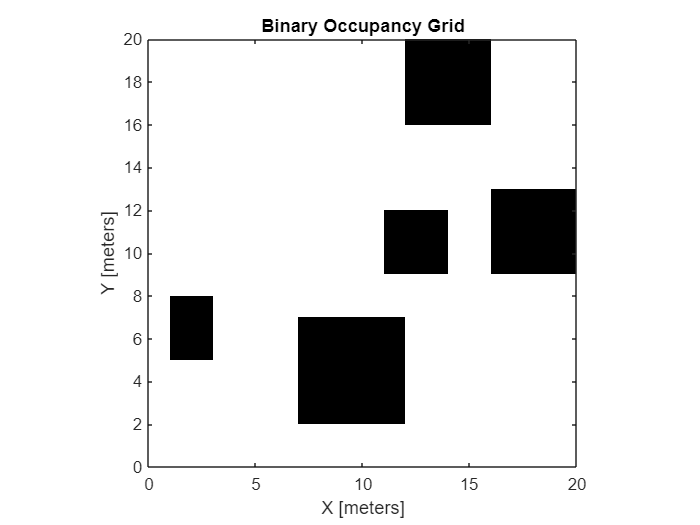

displayMap = true;
if(displayMap) 
    show(omap); 
end